# Dyskretna transformacja Fouriera

#### 28.11.2024, Mateusz Wójcik

Istnieje wiele różnych zastosowań **Dyskretnej transformaacji Fouriera. **Spotyka się ją w większości miejsc, gdzie potrzebne jest wykonanie jakiejś operacji na danych. Między innymi w przetwarzaniu sygnałów, zastosowanie DFT pozwala analizę sygnałów w domenie częstotliwościowej, kompresję danych. Oprócz tego DFT stosuje się w filtracji sygnałów, czy to zniwelowania zakłóceń, czy do skupienia się na interesującym nas zakresie widma częśtotliwościowego sygnału. Przy wykorzystaniu DFT, mozna również analizować obrazy, badać wzorce na obrazach, oraz kompresować ich rozmiar. Detekcja pewnych własności sygnału jest również porządaną aplikacją, w której korzysta się z DFT. Te wszystkie własności sprawiają, że Dyskrtetna Transformacja Fouriera stosowana jest w wielu różnych dziedzinach takich jak: Inżynieria dźwięku i akustyka, telekomunikacja, kryptografia (do analizy losowości danych), bioinformatyka, systemy wizyjne, finanse, geofizika.

## Zad 1

DFT  sygnału sinusoidalnego, przy wykorzystaniu częstotliwości próbkowania $f_p = 1000 \ [Hz]$

clear
syms t w

% Dane do zbierania danych
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;

% Dane opisujące przebieg sygnału
A0 = 5;
A1 = 10; 
f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;

tn = (0:N-1)* Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);


for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk(k+1) = sum(arrayfun(@(n) xn(n) * exp(-1i * 2 * pi/N*(k)*(n-1)), 1:N));
    end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk));
disp('DFT error:'); disp(dft_err);

DFT error:
   1.2616e-13



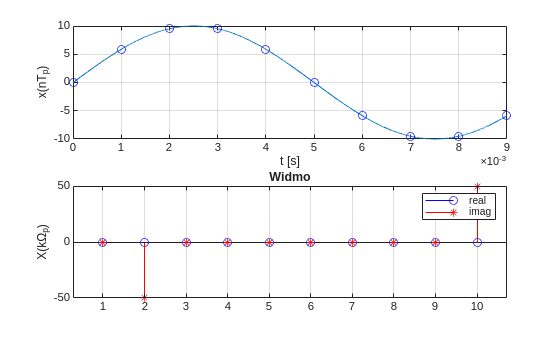

figure;
subplot(2,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

## Zadanie 2

Aby nadać sensu fizycznego osi x, należy przeskalować wartości k, odpowiadającym im częstotliwością. Wykonuje się to przy użyciu wzoru podanego poniżej:


$$f(k) = \frac{1}{T_p} \frac{k}{N} = f_p \frac{k}{N} $$
 

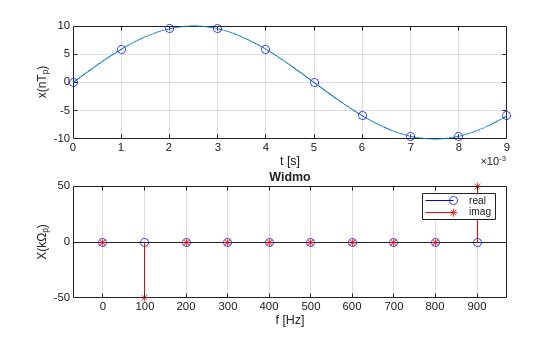

f = fp/N * (0:N-1);
figure;
subplot(2,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
stem(f, real(Xk),'ob'); grid on, hold on
stem(f, imag(Xk),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

## Zadanie 3

Na wcześniejszych wykresach DFT, były uwzględnione zarówno częstotliwości dodatnie jak i ujemne, dlatego, wybrano N/2 (bo N jest parzyste) pierwszych próbek zarówno z wektora częstotliwości, jak i z widma częstotliwościowego.

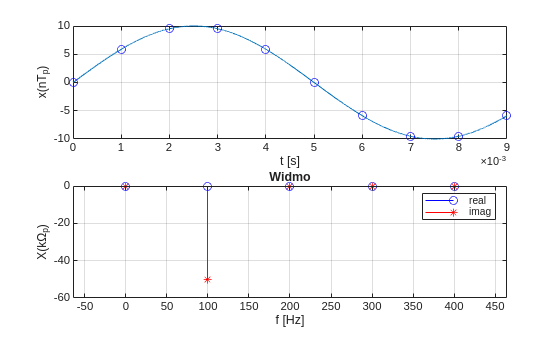

figure;
subplot(2,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
stem(f(1:N/2), real(Xk(1:N/2)),'ob'); grid on, hold on
stem(f(1:N/2), imag(Xk(1:N/2)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

## Zadanie 4

Utworzenie dodatkowych wykresów przedstawiających dodatkowo widmową gęstość amplitudową oraz gęstość fazy sygnału.

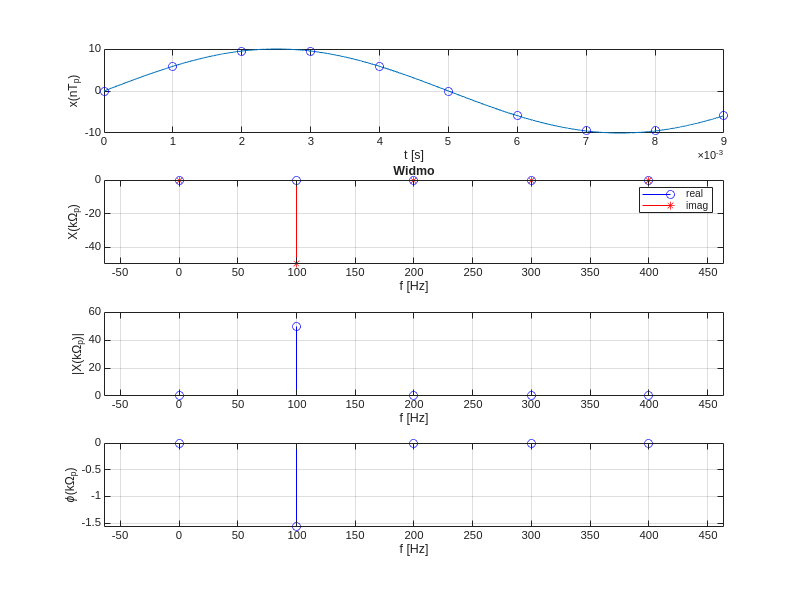

tol = 10e-5;
Xk( abs(Xk) < tol ) = 0;

figure(Position=[100, 100, 800, 600]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:N/2), real(Xk(1:N/2)),'ob'); grid on, hold on
stem(f(1:N/2), imag(Xk(1:N/2)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')
subplot(4,1,3)
stem(f(1:N/2), abs(Xk(1:N/2)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|'); %xlabel('f [Hz]')

subplot(4,1,4)

stem(f(1:N/2), angle(Xk(1:N/2)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)'); %xlabel('f [Hz]')

## Zadanie 5

Zmiana liczby próbek na 15 i 20:

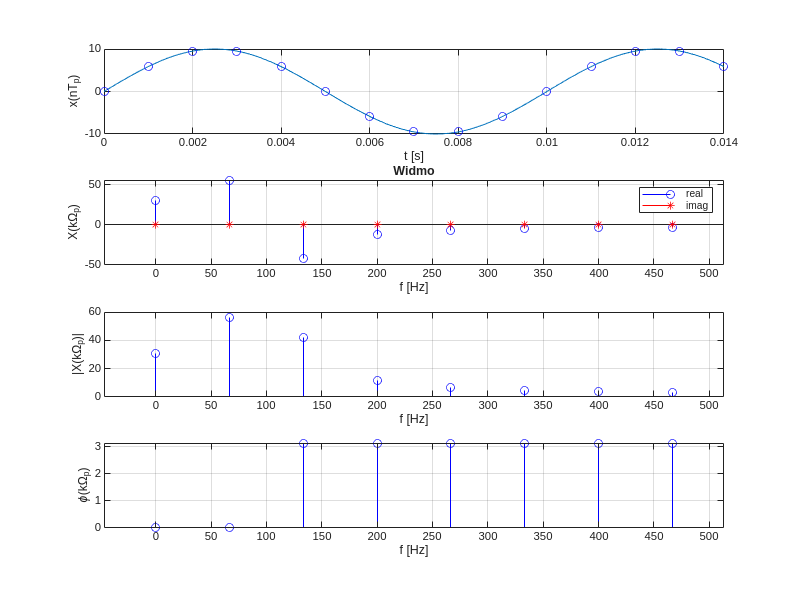

N = 15;
f = fp/N * (0:N-1);
tn = (0:N-1)*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = fft(xn, N);
Xk( abs(Xk) < tol ) = 0;


figure(Position=[100, 100, 800, 600]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:(floor(N/2)+1)), real(Xk(1:(floor(N/2)+1))),'ob');grid on, hold on
stem(f(1:floor(N/2)+1), imag(Xk(1:floor(N/2)+1)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')
subplot(4,1,3)
stem(f(1:floor(N/2)+1), abs(Xk(1:floor(N/2)+1)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|'); %xlabel('f [Hz]')

subplot(4,1,4)

stem(f(1:floor(N/2)+1), angle(Xk(1:floor(N/2)+1)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)'); %xlabel('f [Hz]')

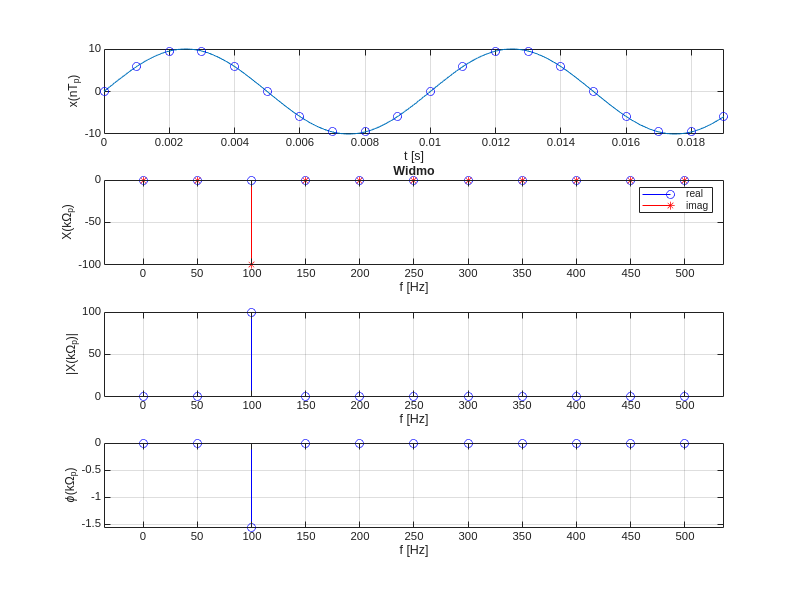

N = 20;
f = fp/N * (0:N-1);
tn = (0:N-1)*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = fft(xn, N);
Xk( abs(Xk) < tol ) = 0;

figure(Position=[100, 100, 800, 600]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:(floor(N/2)+1)), real(Xk(1:(floor(N/2)+1))),'ob');grid on, hold on
stem(f(1:floor(N/2)+1), imag(Xk(1:floor(N/2)+1)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)');

legend('real','imag')
subplot(4,1,3)
stem(f(1:floor(N/2)+1), abs(Xk(1:floor(N/2)+1)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|');
subplot(4,1,4)

stem(f(1:floor(N/2)+1), angle(Xk(1:floor(N/2)+1)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)');

Można zauważyć, że jest to spotkanie z tzw. Przeciekami widma, widać, że dla 15 próbek, nie mamy żadnego punktu, któremu odpowiada częstotliwość $f = 100 \ [Hz]$, dlatego rozkłada się to na resztę częstotliwości.

## Zadanie 6

Kolejny przykład rozlewania się częstotliwości pomiędzy resztę widma, przy źle dobranej liczbie badanych próbek.

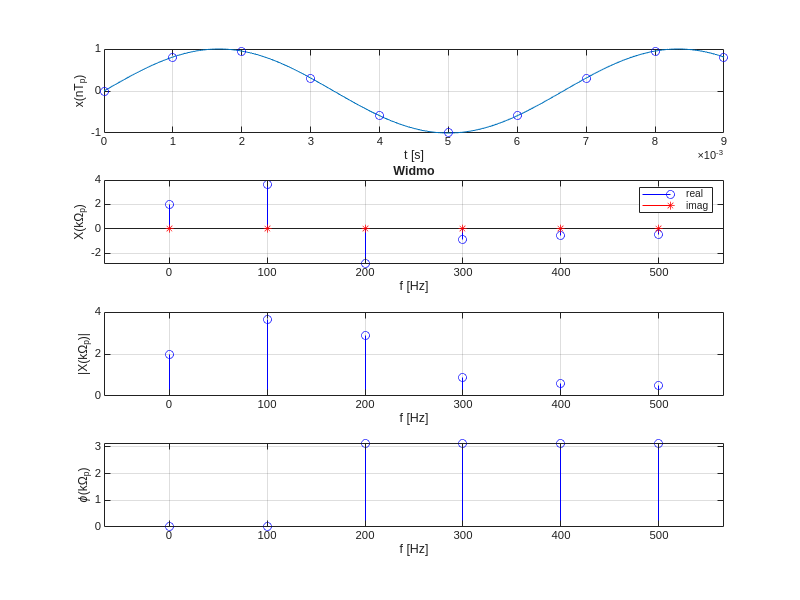

N = 10;
f = fp/N * (0:N-1);

f3 = 150;
x3 = sin(2*pi*f3*t);
x = x3;

tn = (0:N-1)*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = fft(xn, N);
Xk( abs(Xk) < tol ) = 0;

figure(Position=[100, 100, 800, 600]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:(floor(N/2)+1)), real(Xk(1:(floor(N/2)+1))),'ob');grid on, hold on
stem(f(1:floor(N/2)+1), imag(Xk(1:floor(N/2)+1)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)');

legend('real','imag')
subplot(4,1,3)
stem(f(1:floor(N/2)+1), abs(Xk(1:floor(N/2)+1)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|');
subplot(4,1,4)

stem(f(1:floor(N/2)+1), angle(Xk(1:floor(N/2)+1)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)');

## Zadanie 7

W celu redukowania efektu przecieku stosuje się różnego rodzaju okna czasowe. W tym ćwiczeniu przeanalizowanie działania trzech z nich

- **Puls trójkątny:**

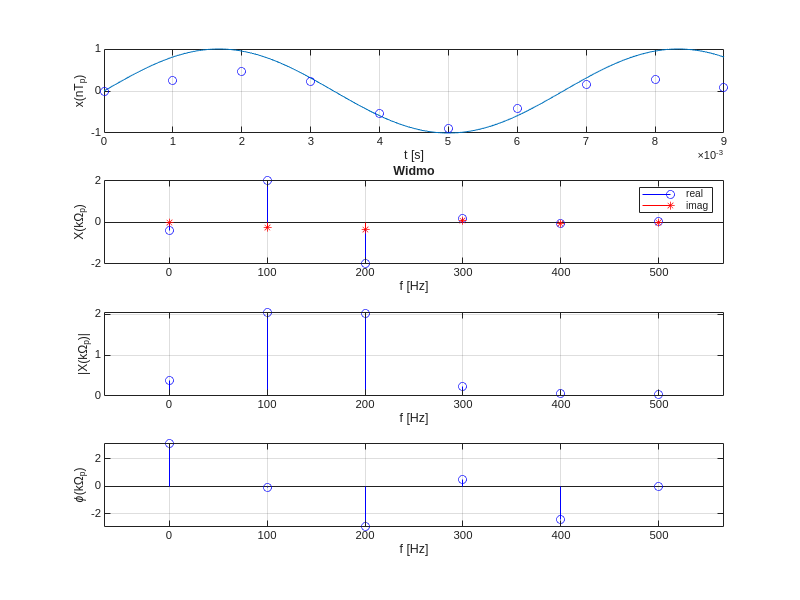

N = 10;
f = fp/N * (0:N-1);

f3 = 150;
x3 = sin(2*pi*f3*t);
x = x3;

tn = (0:N-1)*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*triang(N)';
Xk = fft(xn, N);
Xk( abs(Xk) < tol ) = 0;

figure(Position=[100, 100, 800, 600]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:(floor(N/2)+1)), real(Xk(1:(floor(N/2)+1))),'ob');grid on, hold on
stem(f(1:floor(N/2)+1), imag(Xk(1:floor(N/2)+1)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)');

legend('real','imag')
subplot(4,1,3)
stem(f(1:floor(N/2)+1), abs(Xk(1:floor(N/2)+1)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|');
subplot(4,1,4)

stem(f(1:floor(N/2)+1), angle(Xk(1:floor(N/2)+1)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)');

**2. Okno Gaussa:**

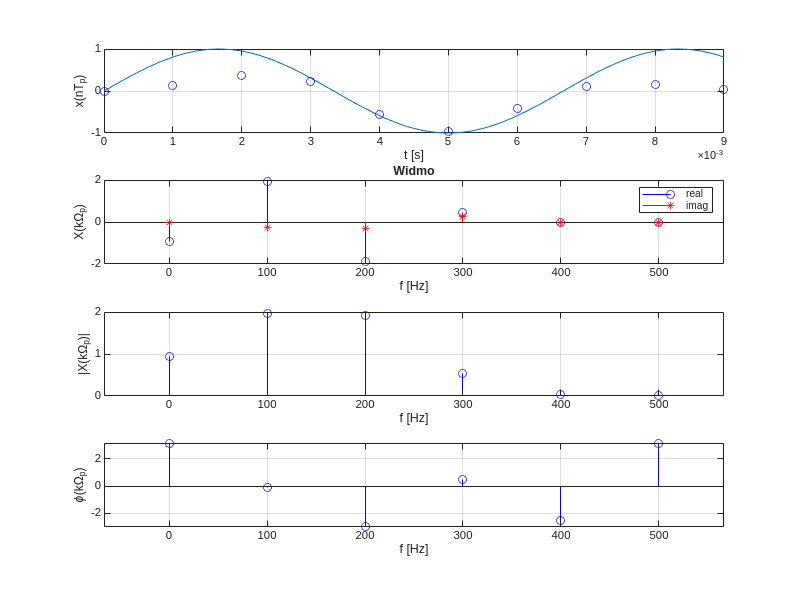

N = 10;
f = fp/N * (0:N-1);

f3 = 150;
x3 = sin(2*pi*f3*t);
x = x3;

tn = (0:N-1)*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*window(@gausswin,N,2.5)';
Xk = fft(xn, N);
Xk( abs(Xk) < tol ) = 0;

figure(Position=[100, 100, 800, 600]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:(floor(N/2)+1)), real(Xk(1:(floor(N/2)+1))),'ob');grid on, hold on
stem(f(1:floor(N/2)+1), imag(Xk(1:floor(N/2)+1)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)');

legend('real','imag')
subplot(4,1,3)
stem(f(1:floor(N/2)+1), abs(Xk(1:floor(N/2)+1)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|');
subplot(4,1,4)

stem(f(1:floor(N/2)+1), angle(Xk(1:floor(N/2)+1)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)');

**3. Okno Hanna**

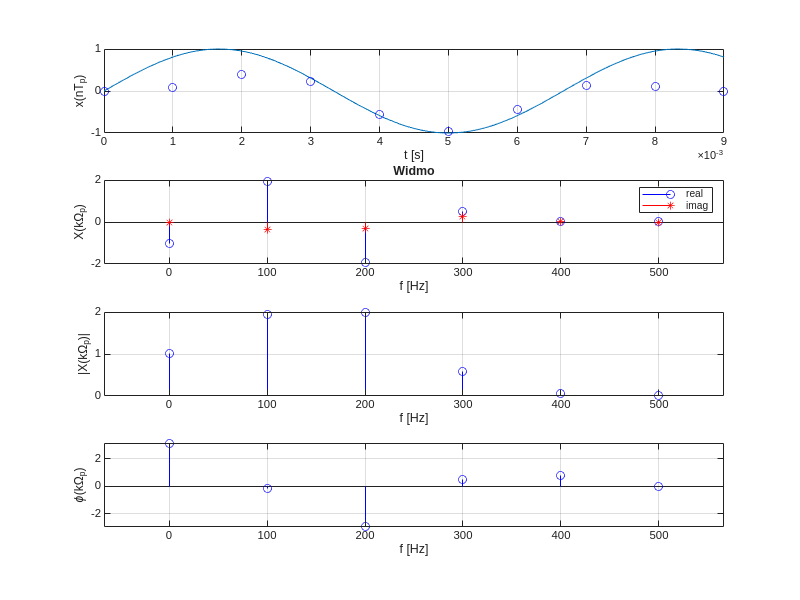

N = 10;
f = fp/N * (0:N-1);

f3 = 150;
x3 = sin(2*pi*f3*t);
x = x3;

tn = (0:N-1)*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
xn = xn.*hann(N)';
Xk = fft(xn, N);
Xk( abs(Xk) < tol ) = 0;

figure(Position=[100, 100, 800, 600]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:(floor(N/2)+1)), real(Xk(1:(floor(N/2)+1))),'ob');grid on, hold on
stem(f(1:floor(N/2)+1), imag(Xk(1:floor(N/2)+1)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)');

legend('real','imag')
subplot(4,1,3)
stem(f(1:floor(N/2)+1), abs(Xk(1:floor(N/2)+1)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|');
subplot(4,1,4)

stem(f(1:floor(N/2)+1), angle(Xk(1:floor(N/2)+1)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)');

Jak można zauwazyć zastosowanie okien znacząco poprawia sygnał zapobiegając przeciekowi widma, jednak nie eliminując go całkowicie. W celu lepszej eliminacji należałoby napewno zwiększyć ilość próbek sygnału, aby posiadać więcej punktów pomiarowych, a na tej podstawie mieć mniejszą różnicę między kolejnymi częstotliwościami.

## Zadanie 8

N = 10;
f = fp/N * (0:N-1);

f2 = 200;
A2 = 5.0

A2 = 5

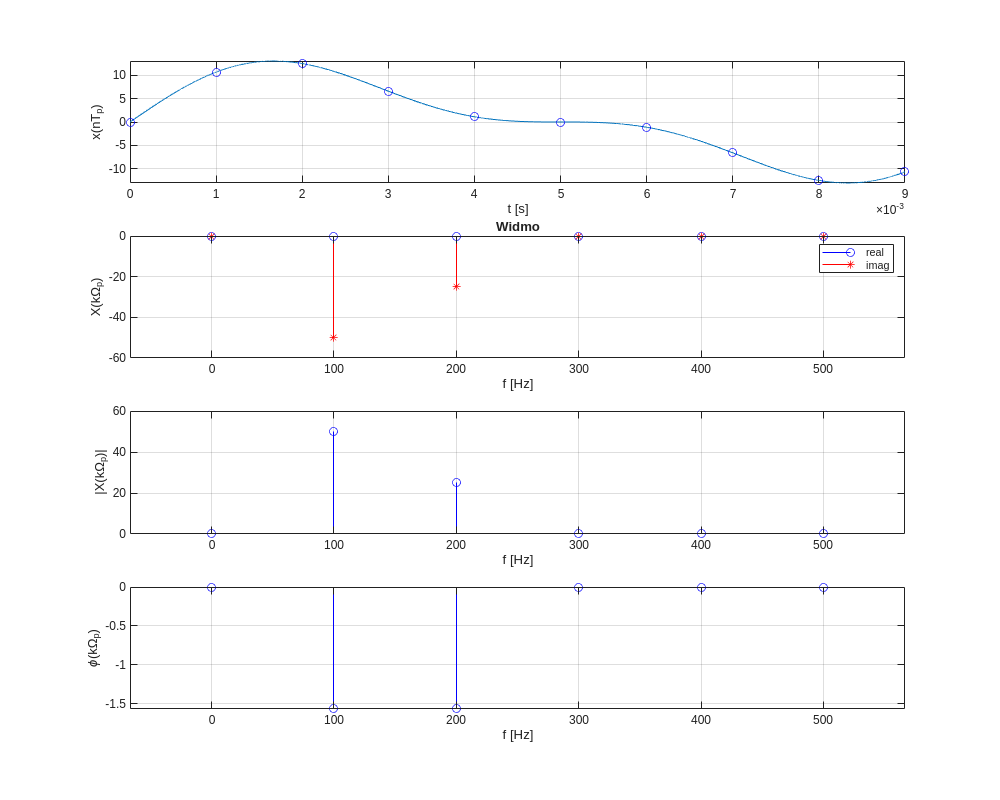

x = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);

tn = (0:N-1)*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = fft(xn, N);
Xk( abs(Xk) < tol ) = 0;

figure(Position=[100, 100, 1000, 800]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:(floor(N/2)+1)), real(Xk(1:(floor(N/2)+1))),'ob');grid on, hold on
stem(f(1:floor(N/2)+1), imag(Xk(1:floor(N/2)+1)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)');

legend('real','imag')
subplot(4,1,3)
stem(f(1:floor(N/2)+1), abs(Xk(1:floor(N/2)+1)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|');
subplot(4,1,4)

stem(f(1:floor(N/2)+1), angle(Xk(1:floor(N/2)+1)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)');

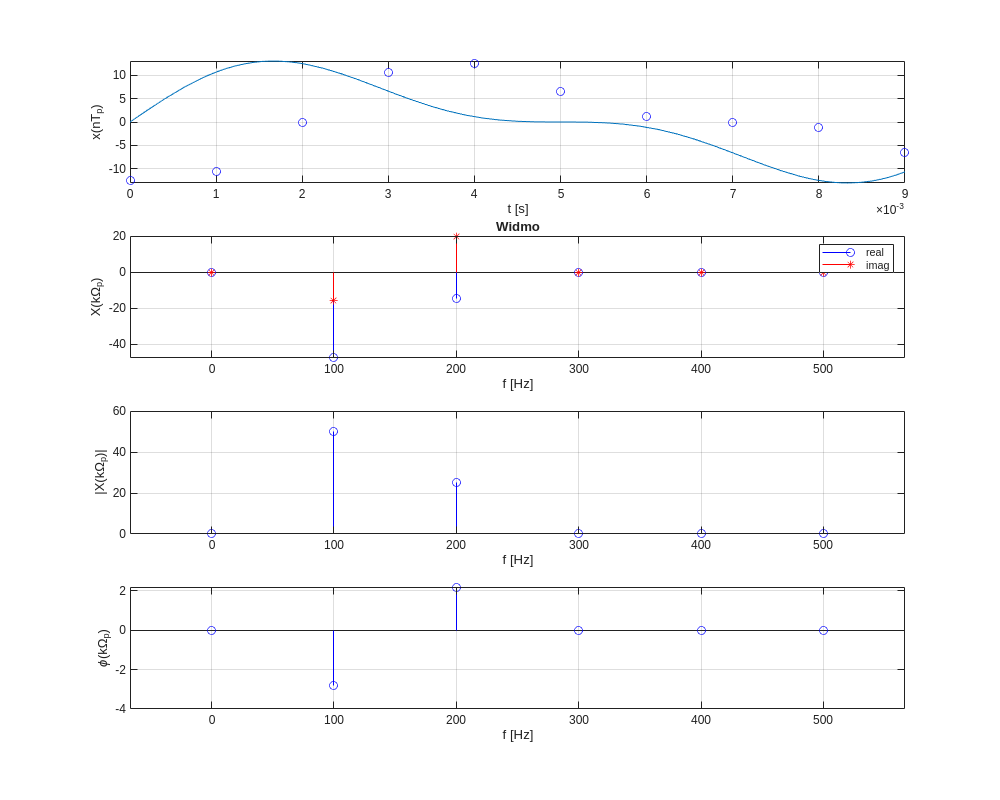

xn = [xn(N-1:N), xn(1:N-2)];
Xk = fft(xn, N);
Xk( abs(Xk) < tol ) = 0;

figure(Position=[100, 100, 1000, 800]);
subplot(4,1,1)
fplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(4,1,2)
stem(f(1:(floor(N/2)+1)), real(Xk(1:(floor(N/2)+1))),'ob');grid on, hold on
stem(f(1:floor(N/2)+1), imag(Xk(1:floor(N/2)+1)),'*r');
title('Widmo'),
xlabel("f [Hz]")
ylabel('X(k\Omega_p)');

legend('real','imag')
subplot(4,1,3)
stem(f(1:floor(N/2)+1), abs(Xk(1:floor(N/2)+1)),'ob'); grid on
xlabel("f [Hz]")
ylabel('|X(k\Omega_p)|');
subplot(4,1,4)

stem(f(1:floor(N/2)+1), angle(Xk(1:floor(N/2)+1)),'ob'); grid on,
xlabel("f [Hz]")
ylabel('\phi(k\Omega_p)');

Jak można zauważyć przesunięcie w prawo sygnału o dwi próbki nie wpłynęło na gęśtość amplitudową sygnału, natomiast zmieniła się odpowiednio gęstość fazy sygnału.

## Zadanie domowe

N = 10;
x = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);
tn = (0:N-1)*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));

Xk1 = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
    for n = 0:N-1
        Xk1(k+1) = sum(arrayfun(@(n) xn(n) * exp(-1i * 2 * pi/N*(k)*(n-1)), 1:N));
    end
end

**Implementacja macierzowa:**

rows = N;
cols = N;

[n, k] = ndgrid(0:N-1, 0:N-1);

% Calculate the matrix of exponents
dft_matrix = exp(-1i * 2 * pi/N *k.*n);

Xk2 = xn * dft_matrix;

**Porównanie obu metod:**

Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err1 = sum(abs(Xk_fft-Xk1));
dft_err2 = sum(abs(Xk_fft-Xk2));
disp('Implementacja przy użyciu pętli: DFT error:'); disp(dft_err1);

Implementacja przy użyciu pętli: DFT error:
   1.5487e-13



disp('Implementacja macierzowa: DFT error:'); disp(dft_err2);

Implementacja macierzowa: DFT error:
   1.5701e-13



Jak można zauważyć obie metody dają zbliżone wyniki, natomiast implementacja macierzowa pozwala na znacznie szybsze wykonanie, w porównaniu do wykorzystania operacji w pętli.

## Wnioski

Dyskretna transformacja Fouriera (DFT) znajduje szerokie zastosowanie w analizie sygnałów, obrazów oraz innych dziedzinach nauki i techniki.  Dzięki niej możliwe jest przejście z domeny czasowej do domeny częstotliwościowej, co pozwala na szczegółową analizę widma sygnałów, identyfikację ich cech oraz eliminację zakłóceń. Przykłady zastosowań  DFT obejmują przetwarzanie sygnałów audio, analizę obrazów,  telekomunikację, bioinformatykę czy diagnostykę medyczną. Wszystkie te operacje można przeprowadzić na urządzeniach cyfrowych, czyli np. na komputerach, mikrokontrolerach, układach FPGA.

W trakcie laboratorium poczyniono kilka obserwacji, stwierdzono  m. in. że jakość wyników DFT zależy od liczby próbek sygnału oraz zastosowannych odpowiednich okien czasowych. Zaobserwowano również efekt przecieku widma. W celu zwalczania negatywnych efektów przecieku widma stosuje się okna czasowe, takie jak Hanninga czy Gaussa, które pozwalają  znacząco poprawić dokładność analizy, choć, aby uzyskać lepsze efekty eliminacji przecieków wymagane jest zwiększenia liczby próbek. 

Porównanie  implementacji pętlowej i macierzowej wykazało, że metoda macierzowa jest znacznie szybsza, przy zachowaniu wysokiej dokładności. W praktyce jdenak wbudowane funkcje, takie jak `fft`, upraszczają obliczenia, zapewniając równocześnie optymalną wydajność i precyzję.